adsTrain = audioDatastore(fullfile('Daten', 'Sprachkommandos', 'train'), ...
   "IncludeSubfolders",true, 'LabelSource','foldernames');
adsTest = audioDatastore(fullfile('Daten', 'Sprachkommandos', 'test'), ...
   "IncludeSubfolders",true, 'LabelSource','foldernames');
% Klassenverteilung der Trainingsdaten auflisten:
tabulate(adsTrain.Labels);

  Value    Count   Percent
     go      750     25.00%
   left      750     25.00%
  right      750     25.00%
   stop      750     25.00%


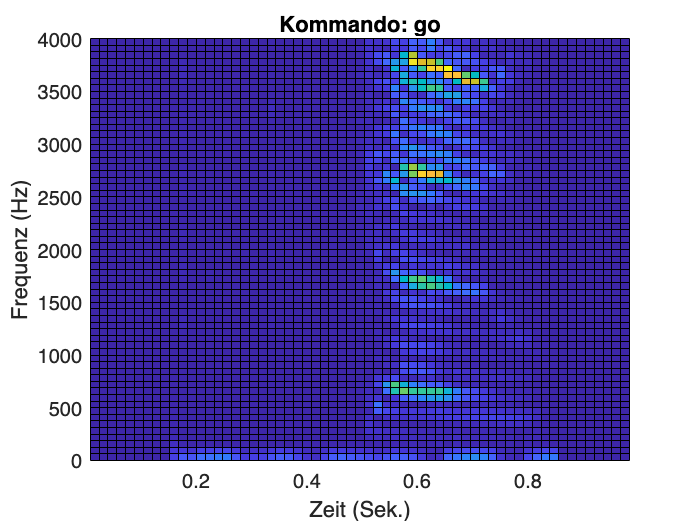

[~, fs] = audioread(adsTrain.Files{1});
win = hamming(128); 
[y, i] = adsTrain.read(); 
[specMat, f,t] = spectrogram(y, win, 0, length(win), fs); 
figure; 
pcolor(t, f, abs(specMat));
title(sprintf('Kommando: %s', i.Label)); 
xlabel('Zeit (Sek.)'), ylabel('Frequenz (Hz)');

C = length(categories(adsTrain.Labels));    % Anzahl Klassen
nTrain = length(adsTrain.Labels);
nTest = length(adsTest.Labels);
P = numel(specMat);      % Anzahl Merkmale


count = 0; 
trainMat = zeros(65, 62, 1, nTrain);
adsTrain.reset();     % Lesepointer auf Anfang setzen
tic
while adsTrain.hasdata()
   % disp(count);
   count = 1 + count;
   [y, i] = adsTrain.read(); 
   assert(i.SampleRate == 8000);   % Haben alle Dateien die gleiche Abtastrate? 
   % Spectrogramm erzeugen und in trainMat schreiben...
   [sm, f, t] = spectrogram(y, win, 0, length(win), i.SampleRate); 
   % TODO: ab hier weiter machen!
   trainMat(:, :, 1, count) = sm;
end

toc

Elapsed time is 47.670930 seconds.


assert(count == nTrain);

layers = [
    imageInputLayer([65 62 1])
    convolution2dLayer(20, 80)
    reluLayer
    convolution2dLayer(5, 20)
    reluLayer
    convolution2dLayer(10, 20)
    reluLayer
    batchNormalizationLayer
    %maxPooling2dLayer(2, 'Stride', 2)
    fullyConnectedLayer(4)
    softmaxLayer
    classificationLayer
];

options = trainingOptions('adam', 'MaxEpochs', 50, 'InitialLearnRate', 0.01);
net = trainNetwork(abs(trainMat), adsTrain.Labels, layers, options);

Error using trainNetwork
Invalid network.

Caused by:
    Layer 6: Input data must have one spatial dimension only, one temporal dimension only, or one of each.
    Instead, it has 2 spatial dimensions and 0 temporal dimensions.


count = 0; 
testMat = zeros(65, 62, 1, nTest);
adsTest.reset();     % Lesepointer auf Anfang setzen
tic
while adsTest.hasdata()
   % disp(count);
   count = 1 + count;
   [y, i] = adsTest.read(); 
   assert(i.SampleRate == 8000);   % Haben alle Dateien die gleiche Abtastrate? 
   % Spectrogramm erzeugen und in trainMat schreiben...
   [sm, f, t] = spectrogram(y, win, 0, length(win), i.SampleRate); 
   % TODO: ab hier weiter machen!
   testMat(:, :, 1, count) = sm;
end

toc

Elapsed time is 33.515756 seconds.


assert(count == nTest);

tic
[yneu, pMat] = classify(net, abs(testMat));
toc

Elapsed time is 3.007417 seconds.



testErr = sum(yneu ~= adsTest.Labels) / length(adsTest.Labels);